# Generador de la Señal de Prueba

## Generador de Ruido Blanco

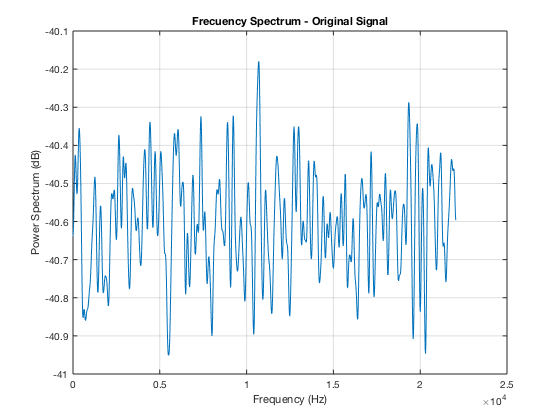

clc
clear all

fs=44100;
t_total=5;

total_samples=44100*t_total;

original_signal=awgn(zeros(total_samples,1),100,100);
original_signal=original_signal*(0.5/max(original_signal));

[pxx,f] = pspectrum(original_signal,fs,'FrequencyResolution',150);  
plot(f,pow2db(pxx)) 
grid on
title("Frecuency Spectrum - Original Signal")
xlabel('Frequency (Hz)') 
ylabel('Power Spectrum (dB)') 

## Filtramos la Señal

%EQ 1Band
HiPass_Parameters=[2000,24];
Out1 = EQ_1Band(original_signal,fs,HiPass_Parameters);

%EQ 2Band
LoShelf_Parameters=[4000,6,2];
Out2 = EQ_2Band(original_signal,fs,HiPass_Parameters,LoShelf_Parameters);

%EQ 3Band
HiShelf_Parameters=[14000,6,2];
Out3 = EQ_3Band(original_signal,fs,HiPass_Parameters,LoShelf_Parameters,HiShelf_Parameters);

%EQ 4Band
LoPass_Parameters=[18000,48];
Out4 = EQ_4Band(original_signal,fs,HiPass_Parameters,LoShelf_Parameters,HiShelf_Parameters,LoPass_Parameters);

%EQ 5Band
Bell1_Parameters=[6000,-12,4,2];
Out5 = EQ_5Band(original_signal,fs,HiPass_Parameters,LoShelf_Parameters,HiShelf_Parameters,LoPass_Parameters,Bell1_Parameters);

%EQ 6Band
Bell2_Parameters=[8000,12,2.5,4];
Out6 = EQ_6Band(original_signal,fs,HiPass_Parameters,LoShelf_Parameters,HiShelf_Parameters,LoPass_Parameters,Bell1_Parameters,Bell2_Parameters);

%EQ 7Band
Bell3_Parameters=[10000,-18,5,2];
Out7 = EQ_7Band(original_signal,fs,HiPass_Parameters,LoShelf_Parameters,HiShelf_Parameters,LoPass_Parameters,Bell1_Parameters,Bell2_Parameters,Bell3_Parameters);

%EQ 8Band
Bell4_Parameters=[12000,-12,1.5,8];
Out8 = EQ_8Band(original_signal,fs,HiPass_Parameters,LoShelf_Parameters,HiShelf_Parameters,LoPass_Parameters,Bell1_Parameters,Bell2_Parameters,Bell3_Parameters,Bell4_Parameters);




## Graficamos los Distintos Espectros

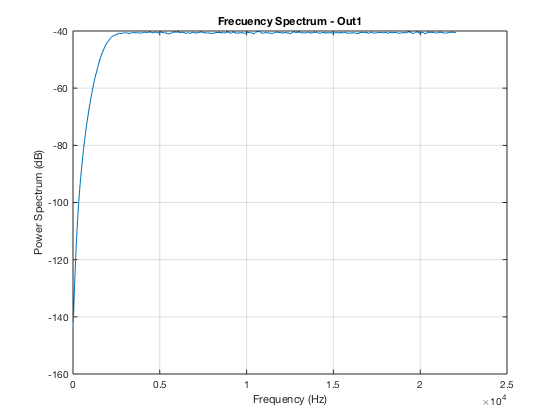


[pxx1,f1] = pspectrum(Out1,fs,'FrequencyResolution',150);  
plot(f1,pow2db(pxx1)) 
grid on
title("Frecuency Spectrum - Out1")
xlabel('Frequency (Hz)') 
ylabel('Power Spectrum (dB)') 

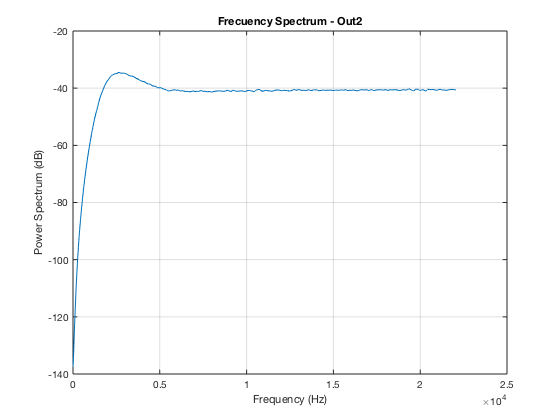


[pxx2,f2] = pspectrum(Out2,fs,'FrequencyResolution',150);  
plot(f2,pow2db(pxx2)) 
grid on
title("Frecuency Spectrum - Out2")
xlabel('Frequency (Hz)') 
ylabel('Power Spectrum (dB)') 

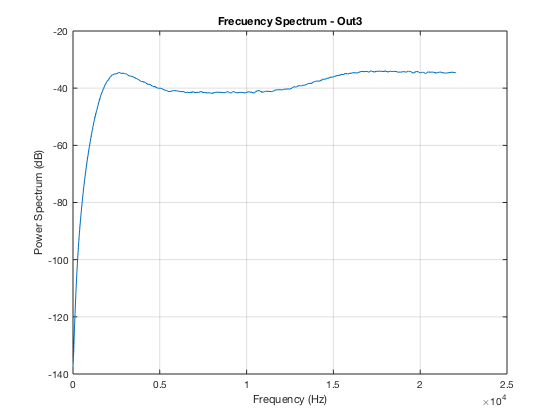


[pxx3,f3] = pspectrum(Out3,fs,'FrequencyResolution',150);  
plot(f3,pow2db(pxx3)) 
grid on
title("Frecuency Spectrum - Out3")
xlabel('Frequency (Hz)') 
ylabel('Power Spectrum (dB)') 

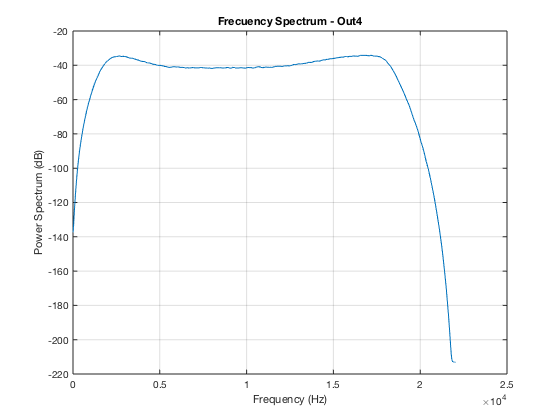


[pxx4,f4] = pspectrum(Out4,fs,'FrequencyResolution',150);  
plot(f4,pow2db(pxx4)) 
grid on
title("Frecuency Spectrum - Out4")
xlabel('Frequency (Hz)') 
ylabel('Power Spectrum (dB)') 

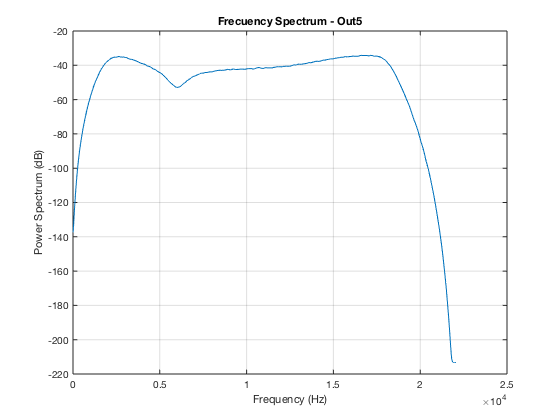


[pxx5,f5] = pspectrum(Out5,fs,'FrequencyResolution',150);  
plot(f5,pow2db(pxx5)) 
grid on
title("Frecuency Spectrum - Out5")
xlabel('Frequency (Hz)') 
ylabel('Power Spectrum (dB)') 

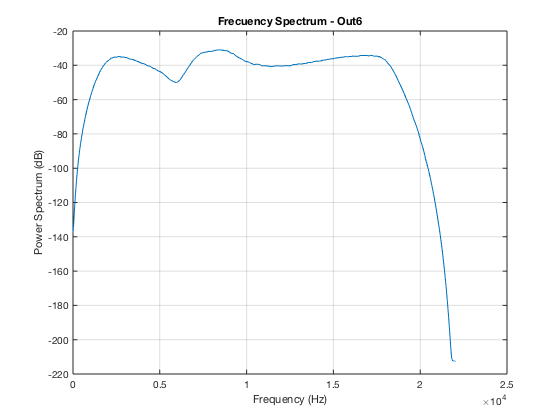


[pxx6,f6] = pspectrum(Out6,fs,'FrequencyResolution',150);  
plot(f6,pow2db(pxx6)) 
grid on
title("Frecuency Spectrum - Out6")
xlabel('Frequency (Hz)') 
ylabel('Power Spectrum (dB)') 

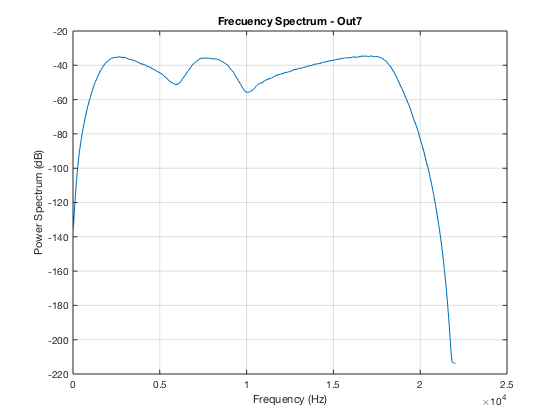


[pxx7,f7] = pspectrum(Out7,fs,'FrequencyResolution',150);  
plot(f7,pow2db(pxx7)) 
grid on
title("Frecuency Spectrum - Out7")
xlabel('Frequency (Hz)') 
ylabel('Power Spectrum (dB)') 

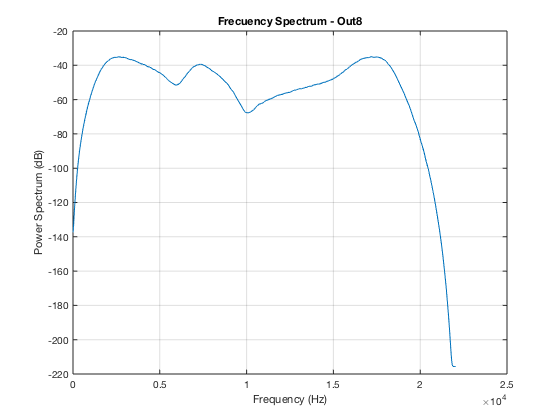


[pxx8,f8] = pspectrum(Out8,fs,'FrequencyResolution',150);  
plot(f8,pow2db(pxx8)) 
grid on
title("Frecuency Spectrum - Out8")
xlabel('Frequency (Hz)') 
ylabel('Power Spectrum (dB)') 

## Guardamos los Archivos .wav de los diferentes filtros

audiowrite("WhiteNoise Original.wav",original_signal,fs);
audiowrite("WhiteNoise Filter1.wav",Out1,fs);
audiowrite("WhiteNoise Filter2.wav",Out2,fs);
audiowrite("WhiteNoise Filter3.wav",Out3,fs);
audiowrite("WhiteNoise Filter4.wav",Out4,fs);
audiowrite("WhiteNoise Filter5.wav",Out5,fs);
audiowrite("WhiteNoise Filter6.wav",Out6,fs);
audiowrite("WhiteNoise Filter7.wav",Out7,fs);
audiowrite("WhiteNoise Filter8.wav",Out8,fs);